ex = [1;0;0];
ey = [0;1;0];
ez = [0;0;1];
zv = [0;0;0];


% kin.H = 2*rand([3 6])-1;
% for i = 1:6
%     kin.H(:,i) = kin.H(:,i) / norm(kin.H(:,i));
% end
% kin.P = 3*rand([3 7]);
% kin.joint_type = zeros([1 6]);
% 
% q = rand([6 1])*2*pi;

kin.H = [ez ex ey];
kin.P = 2*[ez ez+ex ez ez];
kin.joint_type = zeros([1 3]);
%q = [0;0;0];

q1 =0

q1 = 0

q2 =0

q2 = 0

q3 =0

q3 = 0

%q = deg2rad([10;10;10]);
q = deg2rad([q1;q2;q3]);
[R,  p] = fwdkin(kin, q) 

R =      1     0     0
     0     1     0
     0     0     1


p =      2
     0
     8


kin.H = [ez ey ey ex ey ex];
kin.P = 3*[0.78*ez, 0.32*ex, 1.075*ez, 1.1425*ex+0.2*ez, 0*ex, 0*ey, 0.2*ex];
kin.joint_type = zeros([6 1]);
%q = zeros([6 1]);
q = rand([6 1])*2*pi;


h_fig = diagrams.setup;
view(25,30)
hold on

diagrams.robot_plot(kin, q)

ans =   text with properties:

    handle: [1×1 TextBox]
       loc: [3×1 double]


ans =   text with properties:

    handle: [1×1 TextBox]
       loc: [3×1 double]


ans =   text with properties:

    handle: [1×1 TextBox]
       loc: [3×1 double]


ans =   text with properties:

    handle: [1×1 TextBox]
       loc: [3×1 double]


ans =   text with properties:

    handle: [1×1 TextBox]
       loc: [3×1 double]


ans =   text with properties:

    handle: [1×1 TextBox]
       loc: [3×1 double]


ans =   text with properties:

    handle: [1×1 TextBox]
       loc: [3×1 double]


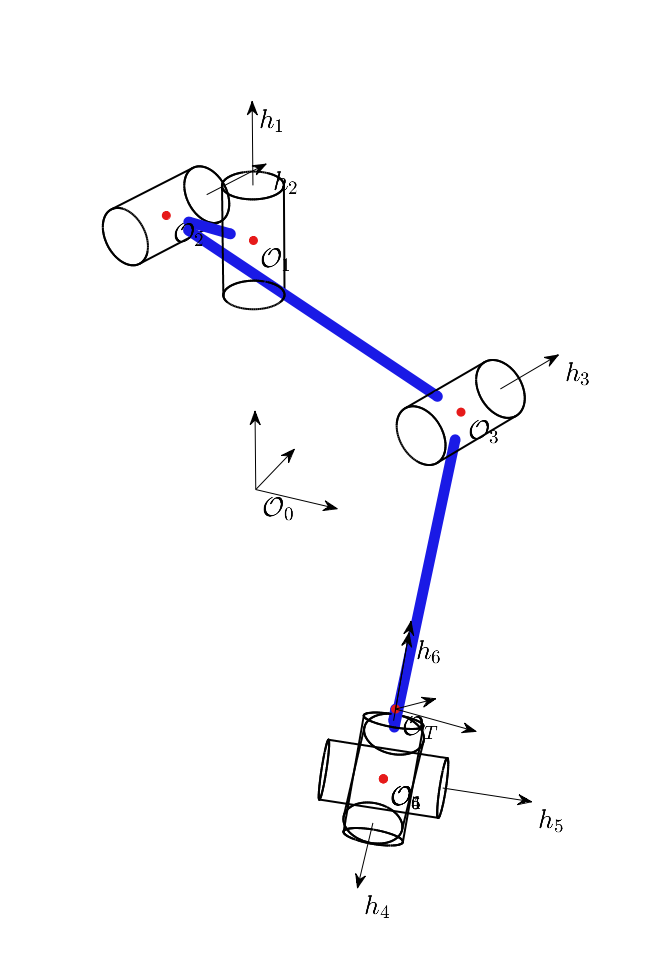


hold off
diagrams.redraw();